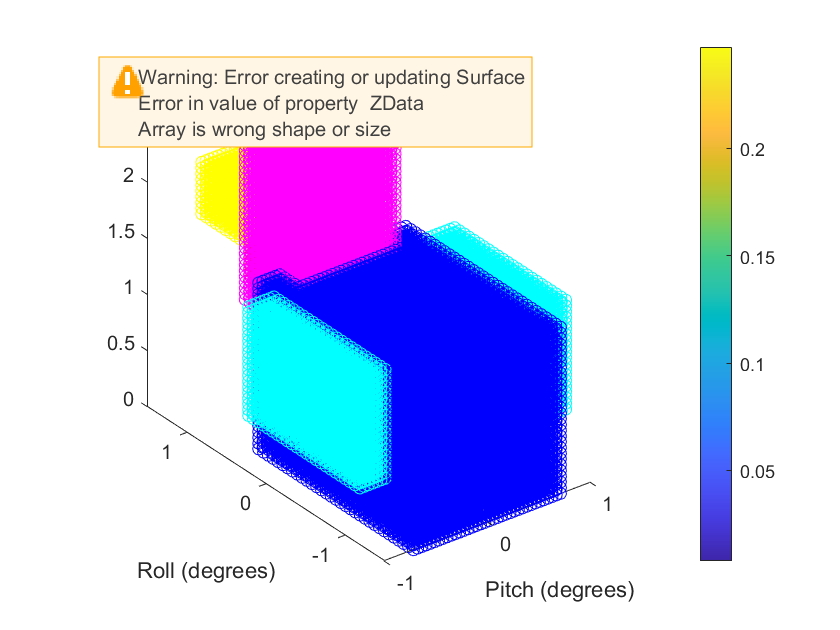

% Constants
rho50 = 10;  % g/in3
rhoWater = 16;   % g/in3
nPoints = 50;

% Define the shape (inches)
xVals = linspace(-1, 1, nPoints); % Wing to wing
yVals = linspace(0, 2.5, nPoints); % Vertical
zVals = linspace(-1.5, 1.5, nPoints); % Beak to butt
[x,y,z] = meshgrid(xVals, yVals, zVals);
points = [x(:), y(:), z(:)];

inBody = points(:,1) <= 0.75 & points(:,1) >= -0.75 & points(:,2) <= 1.5 & points(:,3) <= 0.5 & points(:,3);
inWings = (points(:,1) >= 0.75 | points(:,1) <= -0.75) & points(:,2) >= 0.5 & points(:,2) <= 1.5 & points(:,3) >= -1.25 & points(:,3) <= 0.25;
inHead = points(:,1) >= -0.5 & points(:,1) <= 0.5 & points(:,2) >= 1 & points(:,3) >= 0.25 & points(:,3) <= 1;
inBeak = points(:,1) >= -0.5 & points(:,1) <= 0.5 & points(:,2) >= 1.5 & points(:,2) <= 2 & points(:,3) >= 1;
inWattle = points(:,1) >= -0.25 & points(:,1) <= 0.25 & points(:,2) >= 1 & points(:,2) <= 1.5 & points(:,3) >= 1 & points(:,3) <= 1.25;
inChicken = inBody | inWings | inHead | inBeak | inWattle;

% Plot Chicken
clf;
hold off;
plot3(points(inBody',1), points(inBody',3), points(inBody,2), 'ob');
hold on;
plot3(points(inWings',1), points(inWings',3), points(inWings,2), 'oc');
plot3(points(inHead',1), points(inHead',3), points(inHead,2), 'om');
plot3(points(inBeak',1), points(inBeak',3), points(inBeak,2), 'oy');
plot3(points(inWattle',1), points(inWattle',3), points(inWattle,2), 'or');
axis equal


% Moment Arm Curve
pitchVals = linspace(-180, 180, 30);
rollVals = linspace(-180, 180, 30);
[pitch, roll] = meshgrid(pitchVals, rollVals);
momentArms = zeros(size(pitch));
for i = 1:size(momentArms,1)
    for j = 1:size(momentArms,2)
        momentArms(i, j) = norm(compute_arm([pitch(i, j), roll(i, j)]));
    end
end
figure(2)
surface(pitch, roll, momentArms);
xlabel("Pitch (degrees)");
ylabel("Roll (degrees)");
colorbar
view(3)